# Obtaining stoichiometric compensation parameters (spc) using raw data and binned data

By Tatsuro Tanioka (started Friday, May 19th 2017)

Analyze Martiny POM data at stations (vertically averaged to some depth) and binned by nutrient concentration. Data and MATLAB code was provided by Dr. Eric Galbraith of which he used for the publication Galbraith and Martiny (2015), PNAS.

First, we have some user inputs:

% use lognormal transform?
do_lognorm = true ;
% depth to which to average vertically (from 0)
meandepth = 30. ;

Call the file 'depthmean.m' to calculate station means over some depth range and calculate P:C ratio:

depthmeans % Call the depthmean script

p2c=means.pop ./ means.poc ;
n2c=means.pon ./ means.poc ;

ind=find((means.pop > 0.005) & (means.poc > 0.005) & (means.po4 > 0.001) & (means.po4 < 2) & (p2c > .002) & (p2c < .1));
p2c_rawmean=nanmean(p2c(ind));
p2c_std = nanstd(p2c(ind));

## 1) Line fitting using the raw data (unbinned points)

    (i) Fitting of P:C with the method of Galbraith and Martiny, 2015

Current plot held
Current plot released


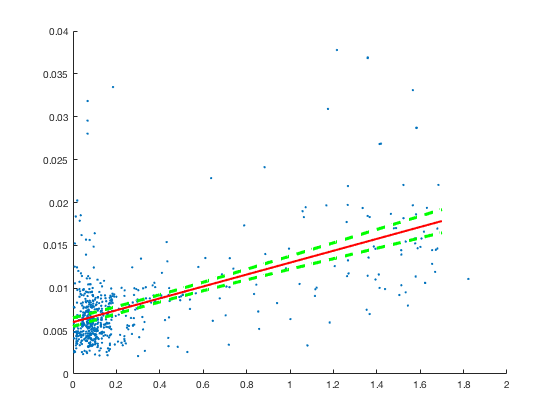

% Calculate P:C linefit with all points
stats_alldata=regstats(p2c(ind),means.po4(ind), 'linear','beta');

%[top_int,bot_int,X] = myregression_line_ci(0.05,stats_alldata.beta,means.po4(ind),p2c(ind),170,0,1.7);
[top_int,bot_int,X] = regression_line_ci(0.05,stats_alldata.beta,means.po4(ind),p2c(ind),170,0,1.7);

funnel_x = X;

mdl = fitlm(means.po4(ind),p2c(ind)) % Shows the result (Intercept, SE, R-squared)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue   
                   _________    __________    ______    ___________

    (Intercept)    0.0060468     0.0002043    29.598    6.4385e-120
    x1             0.0069371    0.00037788    18.358      3.206e-60


Number of observations: 610, Error degrees of freedom: 608
Root Mean Squared Error: 0.00416
R-squared: 0.357,  Adjusted R-Squared 0.356
F-statistic vs. constant model: 337, p-value = 3.21e-60

conf=coefCI(mdl);


 (ii) Fitting of P:C with power-law function

% Calculate P:C vs po4 with power-law function (operating point of 1uM)
%po4_0 = nanmean(means.po4(ind)); % Set mean po4 as the operating po4 conc.
po4_0 = 1.0 % Set 1.0 uM as the operating po4 conc.

po4_0 = 1

modelFunc_p2c_pl2 = @(p,x)(p(1)*(x/po4_0).^p(2)); % Power-law, [P:C}0 = p(1), spc_p = p(2)
Beta2 = [0.0082,0.4]; % Initial guess
mdl_p2c_pl2 = fitnlm(means.po4(ind),p2c(ind),modelFunc_p2c_pl2,Beta2)

mdl_p2c_pl2 = Nonlinear regression model:
    y ~ (p1*(x/po4_0)^p2)

Estimated Coefficients:
          Estimate        SE        tStat       pValue   
          ________    __________    ______    ___________

    p1    0.013314    0.00035351    37.662    4.4419e-161
    p2      0.2816      0.015941    17.665     1.1299e-56


Number of observations: 610, Error degrees of freedom: 608
Root Mean Squared Error: 0.00436
R-Squared: 0.295,  Adjusted R-Squared 0.294
F-statistic vs. zero model: 1.2e+03, p-value = 1.16e-211

       The result with the operating point of 1 um shows that [P:C]0 =  13.0 permil +- 0.3 permil, spc_p =  0.3 +- 0.02. It is important to note that choice of [PO4]0 will not affect the value of s (= slope of a line in log space) but only [P:C]0. R-squared = 0.30, RMSE = 0.00436. For the comparison, linear model had R-squared of 0.36 and RMSE of 0.00416. This shows that power law model fits slightly worse but as equally as good as the linear model. 

(iii) Fitting P:C as a function of PO4 using Morel's function (Morel, 1987, Euqation C1.11)


$$\mathrm{P:C} = \mathrm{(P:C)}_{\max}\cdot \frac{K_1 + \mathrm{P}}{K_2 + \mathrm{P}}$$


Let ${\left(P:C\right)}_{\mathrm{max}} \text{ }=\text{ }0\ldotp 0378\text{ }$(from Dataset) and  we want to estimate K1 and K2. 

% Calculate P:C vs po4 with Morel function 
%modelFunc_p2c_morel = @(p,x)(p(1).*(p(2) + x)./(p(3) + x)); 
modelFunc_p2c_morel = @(p,x)(0.0378.*(p(1) + x)./(p(2) + x)); 
%Beta5 = [0.0378,1.0,1.0]; % Initial guess
Beta5 = [1.0,1.0]; % Initial guess

mdl_p2c_morel = fitnlm(means.po4(ind),p2c(ind),modelFunc_p2c_morel,Beta5)

mdl_p2c_morel = Nonlinear regression model:
    y ~ (0.0378*(p1 + x)/(p2 + x))

Estimated Coefficients:
          Estimate       SE       tStat       pValue  
          ________    ________    ______    __________

    p1    0.49137     0.050826    9.6677    1.1586e-20
    p2     3.2203       0.2406    13.384    5.4433e-36


Number of observations: 610, Error degrees of freedom: 608
Root Mean Squared Error: 0.00418
R-Squared: 0.352,  Adjusted R-Squared 0.351
F-statistic vs. zero model: 1.33e+03, p-value = 9.25e-223

    We obtain K1 = 0.49 uM, K2 = 3.2 uM, R-squared = 0.35, RMSE = 0.00418 = as good as power-law approx. or linear fit. 

(iv) Recasting Morel's formula into Power-law and calculate spc_po4 using the parameters obtained in the nonlinear least square:

   
$$Q_{p} = \mathrm{P:C} = \mathrm{(P:C)}_{\max}\cdot \frac{K_1 + \mathrm{P}}{K_2 + \mathrm{P}} \approx \alpha P^s$$



$$s = \frac{\partial \ln Q_P}{\partial \ln P} = \frac{\partial Q_P}{\partial P}\cdot \frac{P}{Q_p} = \frac{(K_2-K_1)P}{(K_1+P)(K_2+P)}$$


If we take P = 0.6 uM (global surface average) as the operating point, parameters estimated are


$$s = \frac{(3.2-0.49)\cdot0.6}{(0.49+0.6)(3.2+0.6)} = 0.4$$


Qp at the P = 0.6 uM using Morel function is 


$$Q_p = 37.8\times10^{-3} \times \frac{0.49 + 0.6}{3.2 + 0.6} = 10.8\times 10^{-3}$$


which is C:P of 93. 


$$\alpha = Q_p \times P^{-s} = 10.8\times10^{-3} \times (0.6)^{-0.4} = 0.0132$$


These results are consistent with similar the direct fitting of power-law function althought the value of s is slightly higher. To test the sensitivity of s on the choice of operation points we will now plot compute recasted s against operational PO4 concentration:

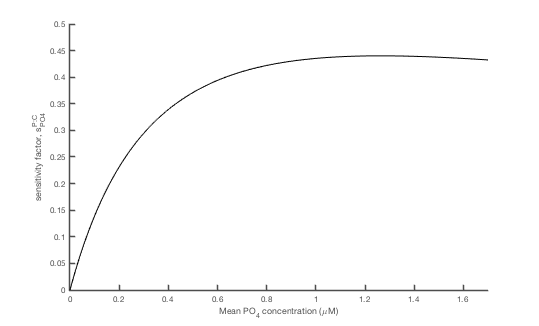

K1 = 0.4912;
K2 = 3.2505;
s_sense = (K2 - K1).*funnel_x./((K1+funnel_x).*(K2+funnel_x));
figure(1)
clf
    x0=10;
    y0=10;
    width=19.0;
    height=11.5;
    hold on
    set(gcf,'units','centimeters','position',[x0,y0,width,height])
set(gcf,'Color','white')
%set(gcf,'units','inches','position',[1 1 10 6])
hold on
    set(gca, ...
    'Box'         , 'off'     , ...
    'TickLength'  , [.01 .01] , ...
    'XMinorTick'  , 'off'      , ...
    'YMinorTick'  , 'off'      , ...
    'YGrid'       , 'off'      , ...
    'XColor'      , [.3 .3 .3], ...
    'YColor'      , [.3 .3 .3], ...
    'LineWidth'   , 1.0 )  
    set( gca , ...
    'FontName', 'Helvetica','FontSize',8,'FontWeight','normal','LineWidth',1.5);
axis([0 1.7 0 0.5])
xlim([0 1.7])
plot(funnel_x,s_sense,'-k')
xlabel('Mean PO{_4} concentration ({\mu}M)','interpreter','tex')
ylabel('sensitivity factor, s^{P:C}_{PO4}','interpreter','tex')
export_fig  f2 -pdf -painters figure2_rev.pdf

%title('Sensitivity of s-parameter against oprational point PO4 conc.')

We can see that for an operational PO4 conc. of 0.6 ~ 1,0 uM, s is approximately 0.4- which can be interepretated as the global mean s.

e.g.) Low-latitude surface mean (0.3uM) -> s = 0.3

        SH High-latitude (1.5 uM) -> s = 0.4

        NH High-latitude (0.89) -> s = 0.43

To summarize: Power-law approx. does as good as linear fit or Morel function in RMSE and slightly worse in R-squared. 

We will now plot a graph showing the scatter plot of data, linear fit of GM15, Morel function, and power-law fit:

% Processing stuff
p2c_nonan=p2c;
p2c_nonan(isnan(p2c))=0;
ind_p2c = find((means.po4> 0.0) & (means.po4<2.3) & (p2c_nonan));
[p2c_fit_morel,p2c_fit_morel_ci] = predict(mdl_p2c_morel,funnel_x'); % Morel P:C
[p2c_fit_pl,p2c_fit_pl_ci] = predict(mdl_p2c_pl2,funnel_x'); % Power-law P:C
% Making a figure
figure(2)
clf
    x0=10;
    y0=10;
    width=19.0;
    height=11.5;
    hold on
    set(gcf,'units','centimeters','position',[x0,y0,width,height])
set(gcf,'Color','white')
%set(gcf,'units','inches','position',[1 1 10 6])
%subplot(2,1,2)
s=scatter(means.po4(ind_p2c),p2c(ind_p2c)*1000,8,'MarkerFaceColor',[0.8,0.8,0.8],'MarkerEdgeColor','none')

s =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: [0.8000 0.8000 0.8000]
           SizeData: 8
          LineWidth: 0.5000
              XData: [1×623 double]
              YData: [1×623 double]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


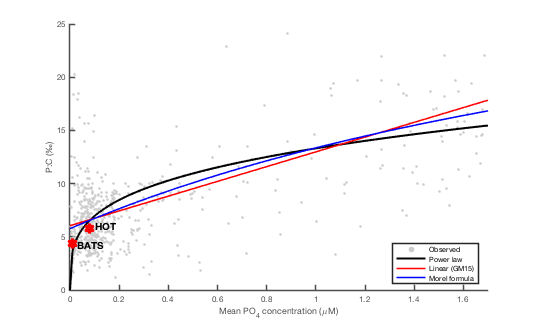

axis([0 1.7 0 25])
hold on
plot(funnel_x,p2c_fit_pl.*1000,'k','LineWidth',2)
hold on
plot(funnel_x, (funnel_x*stats_alldata.beta(2) + stats_alldata.beta(1))*1000, 'r','LineWidth',1.5)
hold on
plot(funnel_x,p2c_fit_morel.*1000,'b','LineWidth',1.5)
hold on
po4_bats = 0.01; % PO4 at BATS (Sarmiento and Gruber, p110)
ptoc_bats = 1000/229; % P:C at BATS (permil) (Martiny et al. 2013, Nat Geo)
po4_hot = 0.08; % PO4 at HOT (Sarmiento and Gruber, p110)
ptoc_hot = 1000/172; % P:C at BATS (permil) (Martiny et al. 2013, Nat Geo)
txt1 = 'BATS';txt2 = 'HOT';
plot(po4_bats,ptoc_bats,'rhexagram','MarkerSize',10,'MarkerFaceColor','red','LineWidth',2)
hold on
plot(po4_hot,ptoc_hot,'rhexagram','MarkerSize',10,'MarkerFaceColor','red','LineWidth',2)
text(0.03,4.2,txt1,'FontSize',10, 'FontName', 'Helvetica','FontWeight','bold')
text(0.1,6.0,txt2,'FontSize',10, 'FontName', 'Helvetica','FontWeight','bold')
hold on
    set(gca, ...
    'Box'         , 'off'     , ...
    'TickLength'  , [.01 .01] , ...
    'XMinorTick'  , 'off'      , ...
    'YMinorTick'  , 'off'      , ...
    'YGrid'       , 'off'      , ...
    'XColor'      , [.3 .3 .3], ...
    'YColor'      , [.3 .3 .3], ...
    'LineWidth'   , 1.0 )  
    set( gca , ...
    'FontName', 'Helvetica','FontSize',8,'FontWeight','normal','LineWidth',1.5);
hXLabel = xlabel('Mean PO{_4} concentration ({\mu}M)','interpreter','tex');
hYLabel = ylabel(sprintf('P:C (%c)',char(8240)));
    set([hXLabel, hYLabel]  , ...
        'FontSize'   , 8          );
legend('Observed','Power law','Linear (GM15)','Morel formula','location','best')
%title('Comparison of Models')
export_fig  f2 -pdf -painters figure1_rev.pdf

%     x0=10;
%     y0=10;
%     width=6.0;
%     height=8.0;
%     hold on
%     set(gcf,'units','centimeters','position',[x0,y0,width,height])
%     pbaspect([1.5 1 1])

## 2) Line fitting using the binned data 

We first define the bin concentrations for PO4 and NO3 (these are same as the ones used by Galbraith and Martiny (2015)).

##     a) Linear Fitting According to GM15

% For P:C and PO4
vpo4 = [0.001 .1 .2 .4 .6 .8 1 1.2 1.4 1.6 ]; % PO4 bin lower limit (uM)
vno3 = [0.0001 1 2 4 7 10 13 16 19 22 25 28 ]; % NO3 bin lower limit (uM)

po4_po4=zeros(length(vpo4)-1) ;
p2c_po4=zeros(length(vpo4)-1) ;

for i=1:length(vpo4)-1
    ind = find((means.po4 > vpo4(i)) & (means.po4 < vpo4(i+1)) & (means.pop > 0.005) & (means.poc > 0.005));
    po4_po4_m(i) = nanmean(means.po4(ind));
    if do_lognorm
        p2c_po4_m(i) = exp(nanmean(log(p2c(ind))));
    else
        p2c_po4_m(i) = nanmean(p2c(ind));
    end
    p2c_po4_std(i) = nanstd(p2c(ind));
    p2c_po4_n(i) = length(p2c(ind));
end
p2c_po4_n % number of data in each bin

p2c_po4_n =    285   150    58    25    12    10    12    21    26


Current plot released
Current plot held


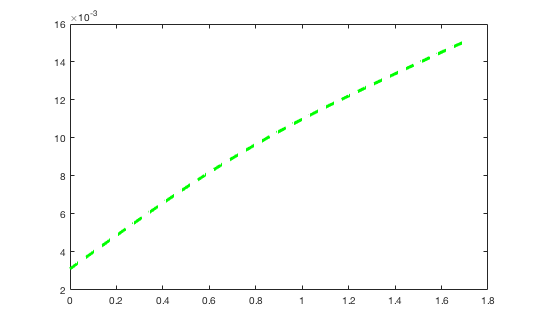


stats_bins=regstats(p2c_po4_m,po4_po4_m, 'linear','beta');

[top_int_bins,bot_int_bins,X] = regression_line_ci(0.05,stats_bins.beta,po4_po4_m,p2c_po4_m,170,0,1.7);


mdl_bins = fitlm(po4_po4_m,p2c_po4_m);
conf_bins = coefCI(mdl_bins);

% Fit a line through the points
p=polyfit(po4_po4_m,p2c_po4_m,1); % polynomial curve fitting of order 1
yfit=polyval(p,po4_po4_m);
yresid = p2c_po4_m - yfit ;
SSresid = sum(yresid.^2) ;
SStotal = (length(p2c_po4_m)-1) * var(p2c_po4_m) ;
rsq_plin = 1 - SSresid/SStotal % R-squared for regression

rsq_plin = 0.9512


% Check correlation with overall data
p2c_nonan=p2c;
p2c_nonan(isnan(p2c))=0;
ind_p2c = find((means.po4> 0.0) & (means.po4<2.3) & (p2c_nonan));
pred_p2c = polyval(p,means.po4(ind_p2c));
[r,pval]=corrcoef(pred_p2c,p2c(ind_p2c));
r2=r .* r;
r2_bins_v_alldata = r2(1,2)

r2_bins_v_alldata = 0.3572


mdl_p_bins = fitlm(po4_po4_m,p2c_po4_m) % Shows the result (Intercept, SE, R-squared)

mdl_p_bins = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue  
                   _________    __________    ______    __________

    (Intercept)    0.0047914    0.00054543    8.7846    4.9922e-05
    x1             0.0072862    0.00062361    11.684    7.6047e-06


Number of observations: 9, Error degrees of freedom: 7
Root Mean Squared Error: 0.000924
R-squared: 0.951,  Adjusted R-Squared 0.944
F-statistic vs. constant model: 137, p-value = 7.6e-06

## b) Fitting with Morel function

modelFunc_p2c_morel2 = @(p,x)(0.0378.*(p(1) + x)./(p(2) + x)); 
%modelFunc_p2c_morel2 = @(p,x)(0.8.*(p(1) + x)./(p(2) + x)); 
%modelFunc_p2c_morel2 = @(p,x)(p(1).*(p(2) + x)./(p(3) + x)); 
Beta5 = [0.34707,1.7224]; % Initial guess
%Beta5 = [0.8,0.6,100]; % Initial guess
mdl_p2c_morel_bin = fitnlm(po4_po4_m,p2c_po4_m,modelFunc_p2c_morel2,Beta5)

mdl_p2c_morel_bin = Nonlinear regression model:
    y ~ (0.0378*(p1 + x)/(p2 + x))

Estimated Coefficients:
          Estimate      SE       tStat       pValue  
          ________    _______    ______    __________

    p1    0.3661      0.11445    3.1988       0.01509
    p2     3.204       0.4416    7.2553    0.00016915


Number of observations: 9, Error degrees of freedom: 7
Root Mean Squared Error: 0.00118
R-Squared: 0.921,  Adjusted R-Squared 0.91
F-statistic vs. zero model: 370, p-value = 7.97e-08

    We obtain K1 = 0.3661 uM, K2 = 3.204 uM, R-squared = 0.92, RMSE = 0.00118 = as good as power-law approx. or linear fit. If we take P = 0.6 uM as the operating point, parameters estimated are


$$s = \frac{(3.2-0.37)\cdot0.6}{(0.37+0.6)(3.2+0.6)} = 0.46 \approx 0.5$$


Qp at the P = 0.6 uM using Morel function is 


$$Q_p = 37.8\times10^{-3} \times \frac{0.37 + 0.6}{3.2 + 0.6} = 9.6 \times 10^{-3}$$


which is C:P of 104. 


$$\alpha = Q_p \times P^{-s} = 9.6\times10^{-3} \times (0.6)^{-0.4} = 0.012$$


To test the sensitivity of s on the choice of operation points we will plot compute recasted s against operational PO4 concentration again. 

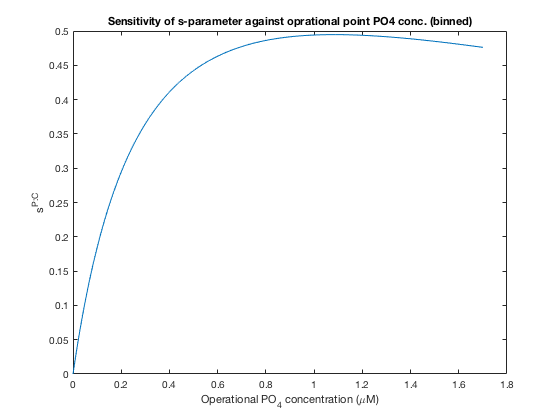

K1_bin = 0.3661;
K2_bin = 3.204;
s_sense_bin = (K2_bin - K1_bin).*funnel_x./((K1_bin+funnel_x).*(K2_bin+funnel_x));
figure(3)
clf
plot(funnel_x,s_sense_bin,'-')
xlabel('Operational PO{_4} concentration ({\mu}M)','interpreter','tex')
ylabel('s^{P:C}','interpreter','tex')
title('Sensitivity of s-parameter against oprational point PO4 conc. (binned)')

We can see that for an operational PO4 conc. of 0.6 ~ 1,0 uM, s is approximately 0.4.

## c) Fitting with Power-law function

mdl_p2c_pl_bin = fitnlm(po4_po4_m,p2c_po4_m,modelFunc_p2c_pl2,Beta2)

mdl_p2c_pl_bin = Nonlinear regression model:
    y ~ (p1*(x/po4_0)^p2)

Estimated Coefficients:
          Estimate        SE        tStat       pValue  
          ________    __________    ______    __________

    p1    0.01242     0.00062142    19.986    1.9641e-07
    p2    0.42918        0.07804    5.4995    0.00090701


Number of observations: 9, Error degrees of freedom: 7
Root Mean Squared Error: 0.00157
R-Squared: 0.859,  Adjusted R-Squared 0.839
F-statistic vs. zero model: 206, p-value = 6.02e-07

    Using the binned-data, we obtained [P:C]0 = 12.4 permil, s = 0.43 +- 0.08, R-squared = 0.86, and RMSE = 0.00157. We will now plot a graph showing the scatter plot of data, linear fit of GM15, Morel function, and power-law fit using binned PO4 conc. vs P:C.

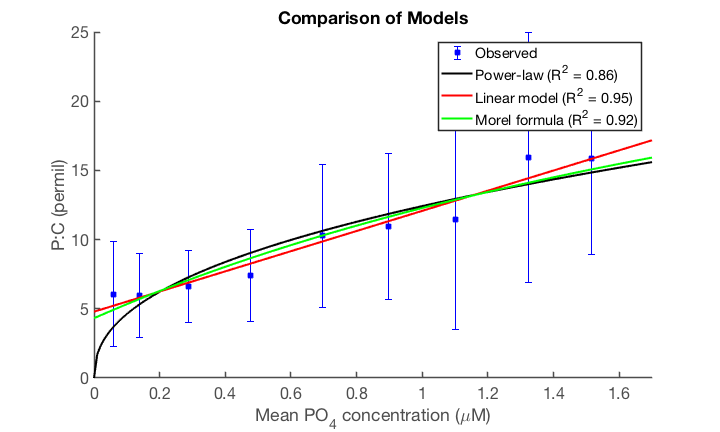

% Processing stuff
p2c_nonan=p2c;
p2c_nonan(isnan(p2c))=0;
ind_p2c = find((means.po4> 0.0) & (means.po4<2.3) & (p2c_nonan));
[p2c_fit_morel_bin,p2c_fit_morel_bin_ci] = predict(mdl_p2c_morel_bin,funnel_x'); % Morel P:C
[p2c_fit_pl_bin,p2c_fit_pl_bin_ci] = predict(mdl_p2c_pl_bin,funnel_x'); % Power-law P:C
% Making a figure
figure(4)
clf
set(gcf,'Color','white')
set(gcf,'units','inches','position',[1 1 10 6])
c = distinguishable_colors(7,'w');   
%subplot(2,1,2)
errorbar(po4_po4_m,p2c_po4_m*1000,p2c_po4_std*1000,'bs','MarkerFaceColor','b')
axis([0 1.7 0 25])
hold on
plot(funnel_x,p2c_fit_pl_bin.*1000,'k','LineWidth',2)
hold on
plot(funnel_x, (funnel_x*stats_bins.beta(2) + stats_bins.beta(1))*1000, 'r','LineWidth',2)
hold on
plot(funnel_x,p2c_fit_morel_bin.*1000,'g','LineWidth',2)
    set(gca, ...
    'Box'         , 'off'     , ...
    'TickLength'  , [.01 .01] , ...
    'XMinorTick'  , 'off'      , ...
    'YMinorTick'  , 'off'      , ...
    'YGrid'       , 'off'      , ...
    'XColor'      , [.3 .3 .3], ...
    'YColor'      , [.3 .3 .3], ...
    'LineWidth'   , 1.0 )  
    set( gca , ...
    'FontName', 'Helvetica','FontSize',16,'FontWeight','normal','LineWidth',1.5);
xlabel('Mean PO{_4} concentration ({\mu}M)','interpreter','tex')
ylabel('P:C (permil)','interpreter','tex')
legend('Observed','Power-law (R^{2} = 0.86)','Linear model (R^{2} = 0.95)','Morel formula (R^{2} = 0.92)')
title('Comparison of Models')

## 4) Fitting power-law curve and linear line to the filtered bulk data

In the original data by GM15, it is evident that there are some data points where P:C values are high even PO4 concentration is low. This is one of the reason why R-squared value for the power-law fit is lower than the linear line. To see if this is actually the case, we used P:C value within the 95% confidence inteval of the GM 15's linear regression. 

For the test, remove points where PO4 < 0.2 uM and P:C > 10 permil.

ind=find((means.pop > 0.005) & (means.poc > 0.005) & (means.po4 > 0.001) & (means.po4 < 2) & (p2c > .002) & (p2c < .1));
p2c_lim = 10.0./1000;
po4_lim = 0.2;
p2c_filt = p2c(ind);
po4_filt = means.po4(ind);
ind_filt = find((p2c_filt < p2c_lim) | (means.po4(ind) > po4_lim));  % Removed points
% Calculate P:C linefit (linear)
stats_alldata_filt=regstats(p2c_filt(ind_filt),po4_filt(ind_filt), 'linear','beta');
mdl = fitlm(po4_filt(ind_filt),p2c_filt(ind_filt))

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE        tStat       pValue   
                   _________    __________    ______    ___________

    (Intercept)    0.0053322    0.00017008    31.352    1.7604e-126
    x1             0.0075628    0.00030587    24.726     1.8961e-92


Number of observations: 576, Error degrees of freedom: 574
Root Mean Squared Error: 0.00334
R-squared: 0.516,  Adjusted R-Squared 0.515
F-statistic vs. constant model: 611, p-value = 1.9e-92

% % Calculate P:C linefit (power-law)
mdl_p2c_pl2_filt = fitnlm(po4_filt(ind_filt),p2c_filt(ind_filt),modelFunc_p2c_pl2,Beta2)

mdl_p2c_pl2_filt = Nonlinear regression model:
    y ~ (p1*(x/po4_0)^p2)

Estimated Coefficients:
          Estimate        SE        tStat       pValue   
          ________    __________    ______    ___________

    p1    0.013479    0.00028151    47.882    1.2841e-202
    p2     0.33813      0.014009    24.137     2.2217e-89


Number of observations: 576, Error degrees of freedom: 574
Root Mean Squared Error: 0.00348
R-Squared: 0.474,  Adjusted R-Squared 0.473
F-statistic vs. zero model: 1.69e+03, p-value = 5.82e-241

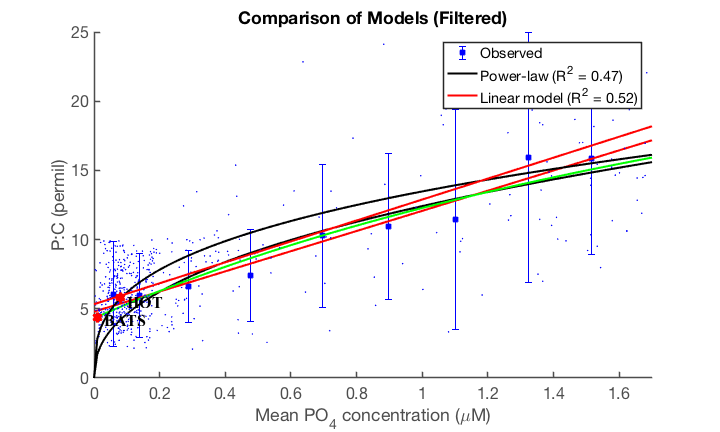

[p2c_fit_pl_filt,p2c_fit_pl_ci_filt] = predict(mdl_p2c_pl2_filt,funnel_x'); % Power-law P:C
% plot
scatter(po4_filt(ind_filt),p2c_filt(ind_filt)*1000,12,'b.')
axis([0 1.7 0 25])
hold on
plot(funnel_x,p2c_fit_pl_filt.*1000,'k','LineWidth',2)
hold on
plot(funnel_x, (funnel_x*stats_alldata_filt.beta(2) + stats_alldata_filt.beta(1))*1000, 'r','LineWidth',2)
hold on
po4_bats = 0.01; % PO4 at BATS (Sarmiento and Gruber, p110)
ptoc_bats = 1000/229; % P:C at BATS (permil) (Martiny et al. 2013, Nat Geo)
po4_hot = 0.08; % PO4 at HOT (Sarmiento and Gruber, p110)
ptoc_hot = 1000/172; % P:C at BATS (permil) (Martiny et al. 2013, Nat Geo)
txt1 = 'BATS';txt2 = 'HOT';
plot(po4_bats,ptoc_bats,'rhexagram','MarkerSize',10,'MarkerFaceColor','red','LineWidth',2)
hold on
plot(po4_hot,ptoc_hot,'rhexagram','MarkerSize',10,'MarkerFaceColor','red','LineWidth',2)
text(0.03,4.2,txt1,'FontSize',16, 'FontName', 'Times','FontWeight','bold')
text(0.1,5.5,txt2,'FontSize',16, 'FontName', 'Times','FontWeight','bold')
hold on
    set(gca, ...
    'Box'         , 'off'     , ...
    'TickLength'  , [.01 .01] , ...
    'XMinorTick'  , 'off'      , ...
    'YMinorTick'  , 'off'      , ...
    'YGrid'       , 'off'      , ...
    'XColor'      , [.3 .3 .3], ...
    'YColor'      , [.3 .3 .3], ...
    'LineWidth'   , 1.0 )  
    set( gca , ...
    'FontName', 'Helvetica','FontSize',16,'FontWeight','normal','LineWidth',1.5);
xlabel('Mean PO{_4} concentration ({\mu}M)','interpreter','tex')
ylabel('P:C (permil)','interpreter','tex')
legend('Observed','Power-law (R^{2} = 0.47)','Linear model (R^{2} = 0.52)')
%legend('boxoff')
title('Comparison of Models (Filtered)')